# Lab 1

## Task 1

### Determine Desired Characteristic Equation

clear; clc;

% Given
zeta = sqrt(2)/2;
omega_n = 2;

syms lambda

% Setting this equation equal to zero yields the desired characteristic
% equation, and finding the roots yields the desired poles

FSF_CE = lambda^2 + 2*zeta*omega_n*lambda + omega_n^2

$$FSF\_CE = \lambda^{2}+2\,\sqrt{2}\,\lambda +4$$

lambda_sol = roots([1, 2*zeta*omega_n, omega_n^2])

lambda_sol =   -1.4142 + 1.4142i
  -1.4142 - 1.4142i


### Determine Gain Matrix (K) for Desired Poles

% System State Space Representation
A = [0 1; -1.62 -0.57];
B = [0; 4];
C = [1 0; 0 1];

% Use MatLab's Acker function to determine the gain matrix
K = acker(A, B, lambda_sol)

K =     0.5950    0.5646


### Run the Simulink Model, lsim Model, and Create Plots

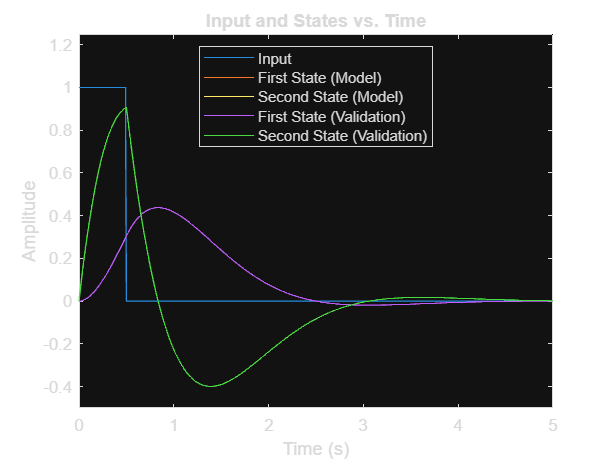

% Runs Simulink Model
out_FSF = runModel(A, B, C, K, 0, "FSF");

% Creates ss representation of system and runs lsim
sys = ss(A - B*K, B, C, 0);
y = lsim(sys, out_FSF.input, out_FSF.tout);

figure
plot(out_FSF.tout, out_FSF.input,...
    out_FSF.tout, out_FSF.ybar(:,1),...
    out_FSF.tout, out_FSF.ybar(:,2),...
    out_FSF.tout, y(:,1),...
    out_FSF.tout, y(:,2));
xlim([0, 5])
ylim([-0.5 1.25])
title("Input and States vs. Time")
xlabel("Time (s)")
ylabel("Amplitude")
legend("Input", "First State (Model)", "Second State (Model)",...
    "First State (Validation)", "Second State (Validation)",...
    "Location", "best")

## Task 2

### Determine Desired Observer Characteristic Equations

syms lambda

% Setting this equation equal to zero yields the desired observer
% characteristic equation; Note that there are three equations for each of
% the three pole placement scenarios

OBS_CE_1 = expand((lambda + 2)^2)

$$OBS\_CE\_1 = \lambda^{2}+4\,\lambda +4$$

lambda_sol_1 = [-2; -2]

lambda_sol_1 =     -2
    -2



OBS_CE_2 = expand((lambda + 4)^2)

$$OBS\_CE\_2 = \lambda^{2}+8\,\lambda +16$$

lambda_sol_2 = [-4; -4]

lambda_sol_2 =     -4
    -4



OBS_CE_3 = expand((lambda + 8)^2)

$$OBS\_CE\_3 = \lambda^{2}+16\,\lambda +64$$

lambda_sol_3 = [-8; -8]

lambda_sol_3 =     -8
    -8


### Determine Gain Matrix (L) for Desired Poles

% Redefine C for the Observer Case
C_obs = [1 0];
% Use MatLab's Acker function to determine the gain matrix
L_1 = acker(A', C_obs', lambda_sol_1)'

L_1 =     3.4300
    0.4249



L_2 = acker(A', C_obs', lambda_sol_2)'

L_2 =     7.4300
   10.1449



L_3 = acker(A', C_obs', lambda_sol_3)'

L_3 =    15.4300
   53.5849


### Run the Simulink Model and Create Plots

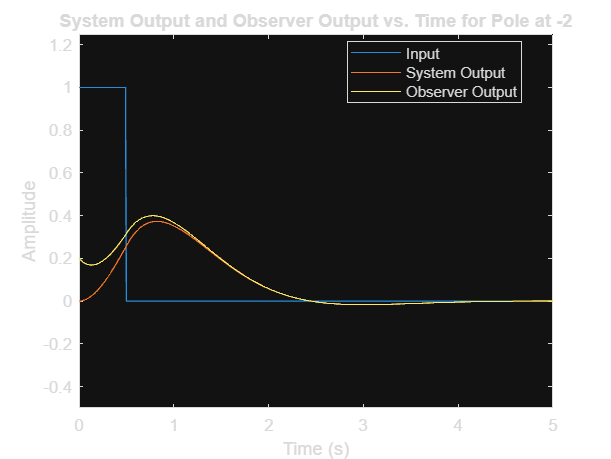

out_OBS_1 = runModel(A, B, C_obs, K, L_1, "OBS");
figure
plot(out_OBS_1.tout, out_OBS_1.input,...
    out_OBS_1.tout, out_OBS_1.ybar,...
    out_OBS_1.tout, out_OBS_1.yhat)
xlim([0, 5])
ylim([-0.5 1.25])
title("System Output and Observer Output vs. Time for Pole at -2")
xlabel("Time (s)")
ylabel("Amplitude")
legend("Input", "System Output", "Observer Output",...
    "Location", "best")

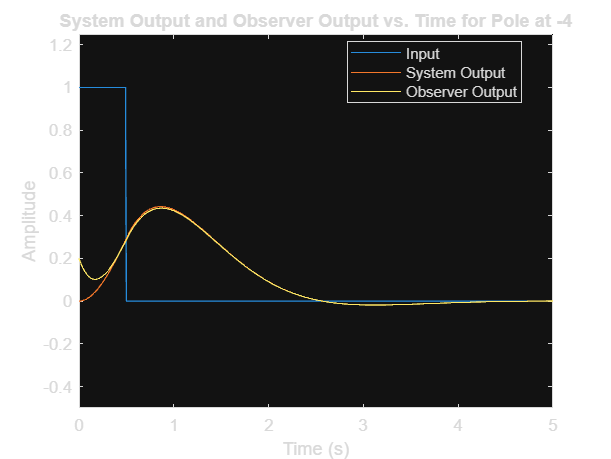


out_OBS_2 = runModel(A, B, C_obs, K, L_2, "OBS");
figure
plot(out_OBS_2.tout, out_OBS_2.input,...
    out_OBS_2.tout, out_OBS_2.ybar,...
    out_OBS_2.tout, out_OBS_2.yhat)
xlim([0, 5])
ylim([-0.5 1.25])
title("System Output and Observer Output vs. Time for Pole at -4")
xlabel("Time (s)")
ylabel("Amplitude")
legend("Input", "System Output", "Observer Output",...
    "Location", "best")

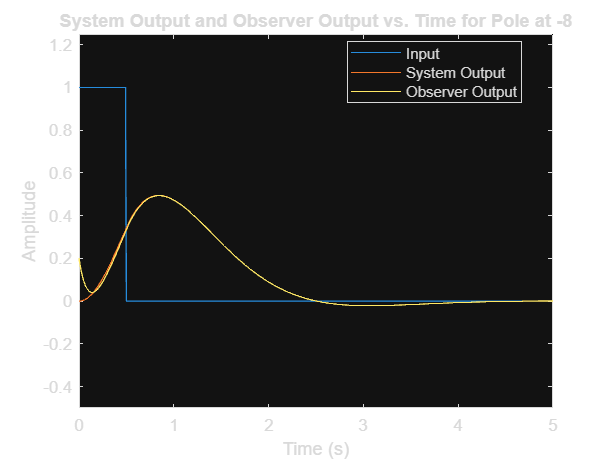


out_OBS_3 = runModel(A, B, C_obs, K, L_3, "OBS");
figure
plot(out_OBS_3.tout, out_OBS_3.input,...
    out_OBS_3.tout, out_OBS_3.ybar,...
    out_OBS_3.tout, out_OBS_3.yhat)
xlim([0, 5])
ylim([-0.5 1.25])
title("System Output and Observer Output vs. Time for Pole at -8")
xlabel("Time (s)")
ylabel("Amplitude")
legend("Input", "System Output", "Observer Output",...
    "Location", "best")